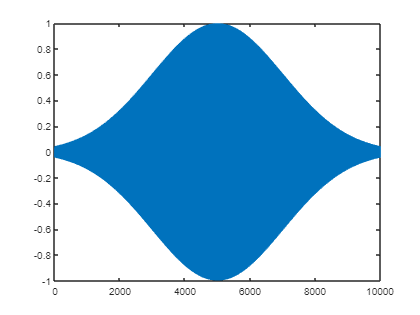

fs = 10000;
x = gausswin(fs);
x = x';
n = 1:fs;
plot(x.*cos(0.2*pi*n));

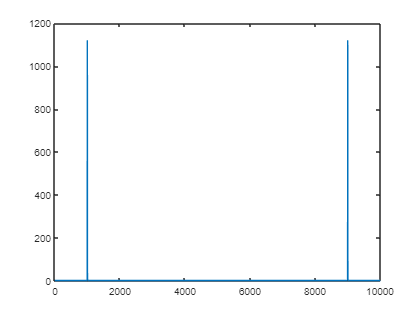

%max(gausswin(fs)');
x = ((gausswin(fs)').^5).*cos(0.2*pi*n);
plot(abs(fft(x)));

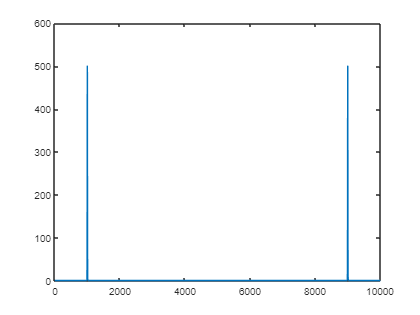

x = ((gausswin(fs)').^25).*cos(0.2*pi*n);
plot(abs(fft(x)));

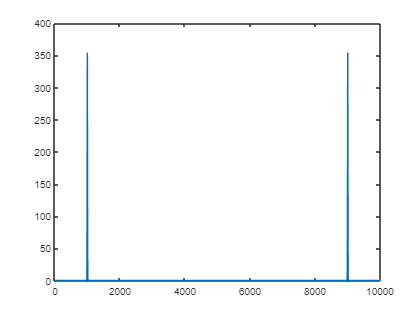

x = ((gausswin(fs)').^50).*cos(0.2*pi*n);
plot(abs(fft(x)));

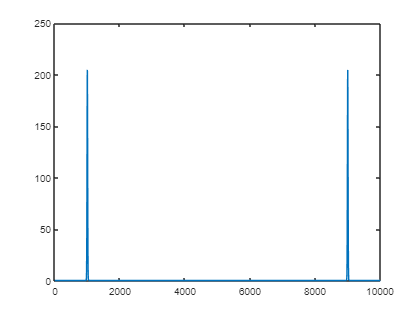

x = ((gausswin(fs)').^150).*cos(0.2*pi*n);
plot(abs(fft(x)));

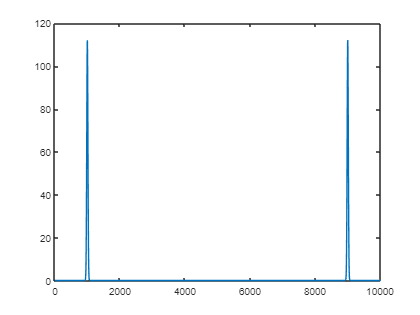

x = ((gausswin(fs)').^500).*cos(0.2*pi*n);
plot(abs(fft(x)));

f_media = freq_media(x,fs)

f_media = 1000

f_media =frequencia(em hertz) média do sinal cujas amostras estâo no vetor 'x'

fs = frequência de amostragem (em hertz) do sinal

function f_media = freq_media(x,fs)                   

    X = fft(x);
    L = round(length(X)/2);
    k = (1:L) - 1;
    num = sum(k.*abs(X(1:round(end/2))).^2);
    den = sum(abs(X(1:round(end/2))).^2);

    k_media = num/den;
    % ceil = arredonda pra cima
    % floor = arredonda pra baixo
    % round = arredonda para o inteiro mais perto

    f_media = (fs/2)*(k_media/L);
    
end